# **IO3xx Resolver Emulation - Setup**

This example demonstrates how to set up the Resolver Emulation code module in combination with the Analog Setup block.

The Simulink model features all the driver blocks required to use the code module.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports **1 x Resolver emulation channel**  

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

- An external signal measuring device, such as an oscilloscope.

### Test Setup

In this example, the internal excitation signal is used to stimulate the Resolver, therefore the analog excitation input will not be used. To measure the generated sin and cos signals you must connect the oscilloscope to the pins (cos+, cos-, sin+, sin-) on the terminal board where the Resolver Emulation channels are located. The exact pins depend on the configuration file (bitstream) used.

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect theses pins with jumper wires.

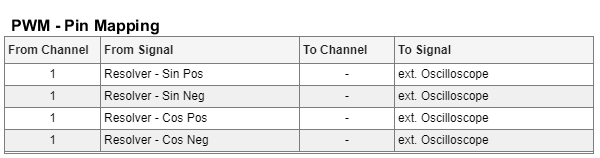

## Initialize and Open the Simulink model

*Add commands to configure parameters and other settings.*

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Resolver_Emulation_Setup';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

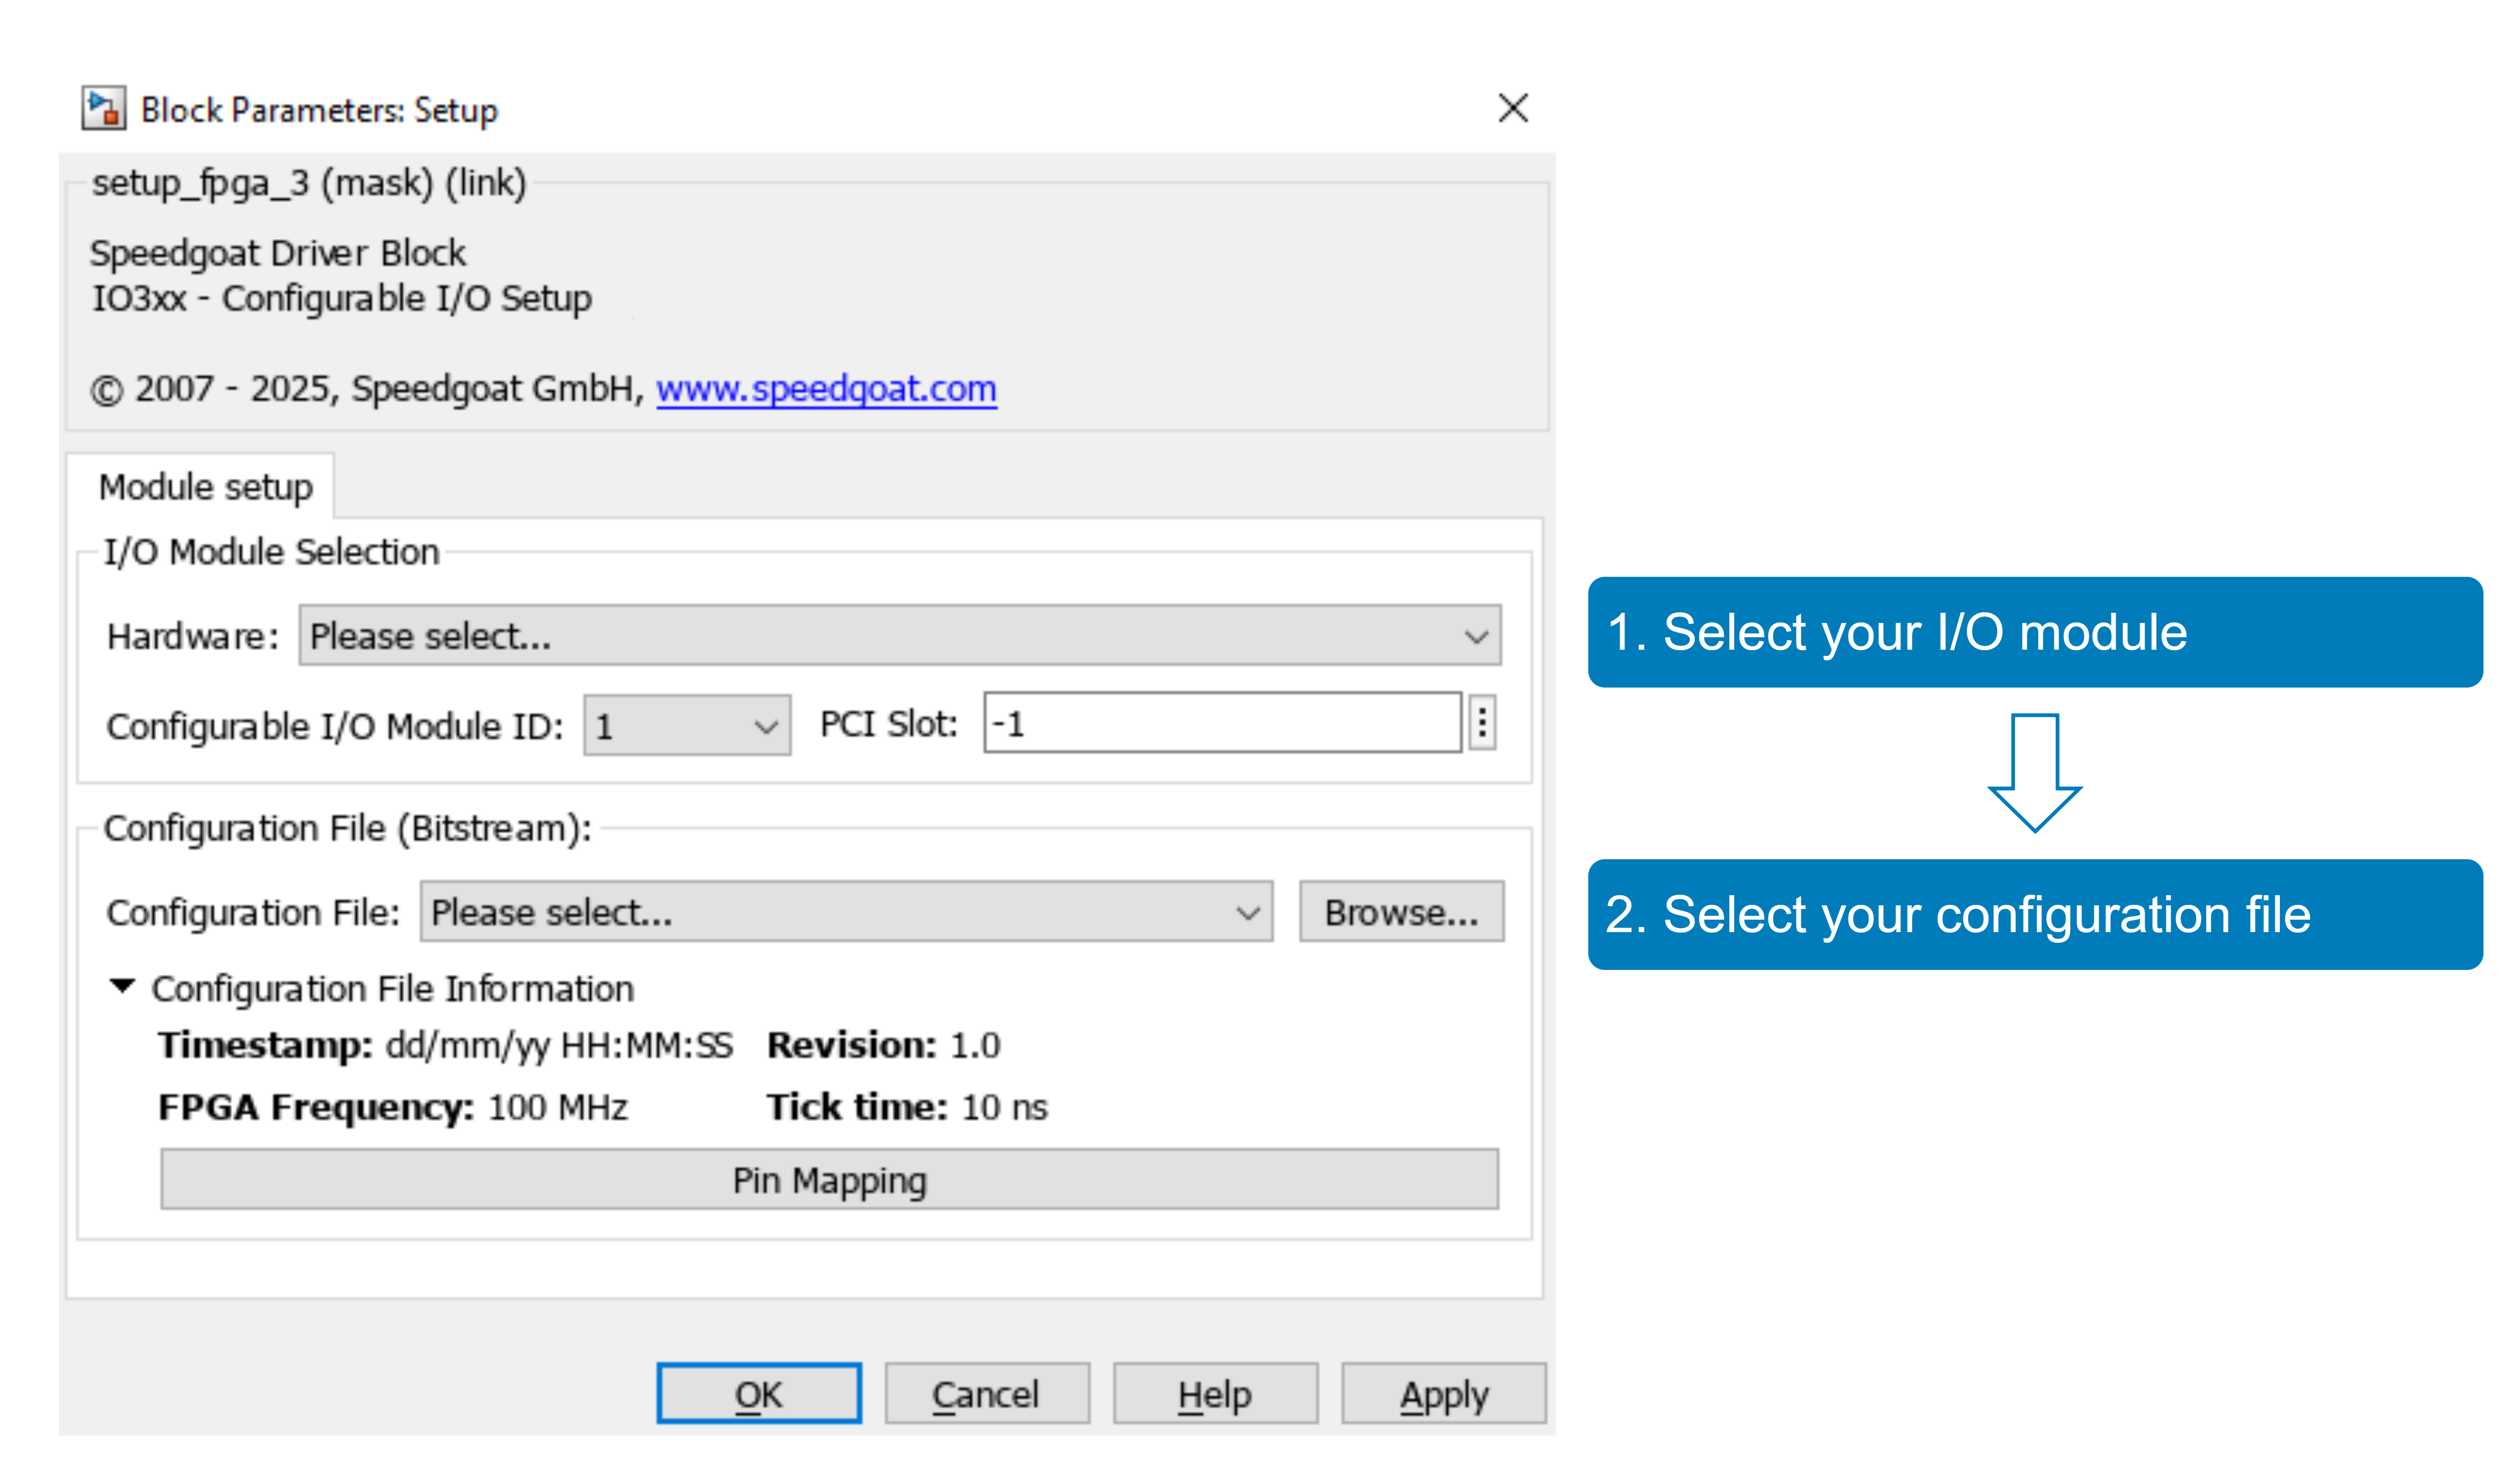

With the **Pin Mapping** button you can now check where the functionalities are located.

In addition to the IO3xx Setup block, the corresponding IO3xx Analog Setup block must be configured. The Analog Setup block will list all the Analog code module functionality available in the configuration file. Select the **Resolver** check box and confirm by clicking **Yes** in the additional window that will pop up. This will enable the code module functionality and automatically reformat the Analog Setup bock for use with the Resolver Emulation code module.

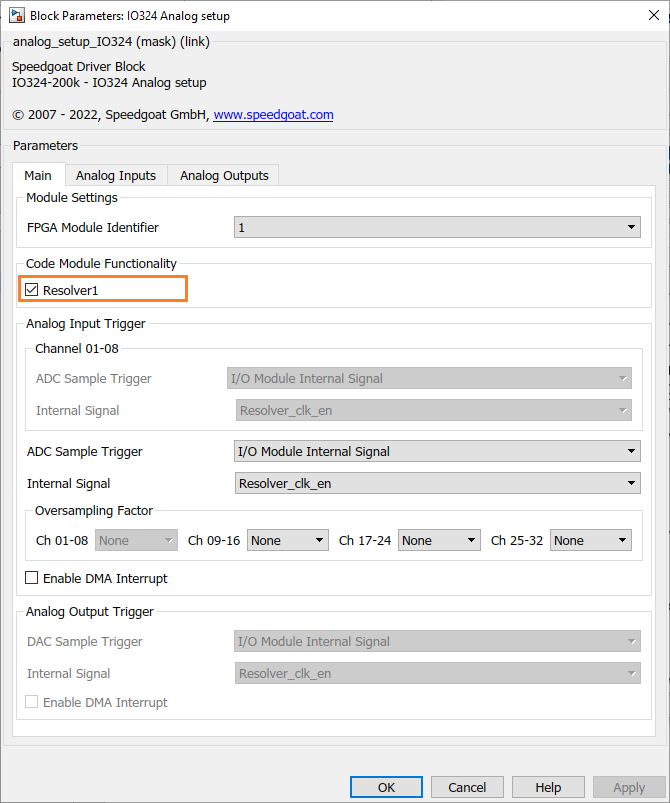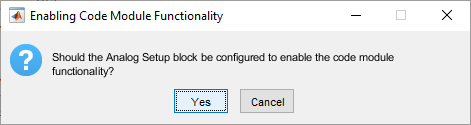

### Model Description

**Code Module Setup**

In the model, an internal excitation signal with a frequency of 1 kHz is used to stimulate the generation of the resolver output signals. The Resolver Emulation code module is configured to use the speed input and is run at a constant rotational speed of 10*2*pi rad/s. The speed is integrated at a small time step on the FPGA to achieve a smooth position signal, which is essential for the operation of the resolver.

**I/O Module Setup**

**Triggering**

The resolver sample time is set to 1 us. The Resolver Emulation code module on the FPGA is therefore triggered every 1 us. In the Analog Setup block, this same trigger signal will be set for the ADC and DAC triggers used by the Resolver Emulation code module. Other ADC and DAC channels, which are in the same group as the resolver channels, will be restricted to using the same trigger.

**Channel Setup**

The channels used by the resolver are automatically selected in the Analog Setup block. Settings such as **Signal Mode (Single-Ended or Differential)** for the analog inputs and the **Voltage Range** for both the ADC and the DAC channels are set to the default value. These settings can still be manually changed in the Analog Setup block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the Resolver Emulation works as expected, the outputs should match the following oscilloscope screenshot.

Scope1: Sin (+)

Scope2: Sin (-)

Scope3: Cos (+)

Scope4: Cos (-)

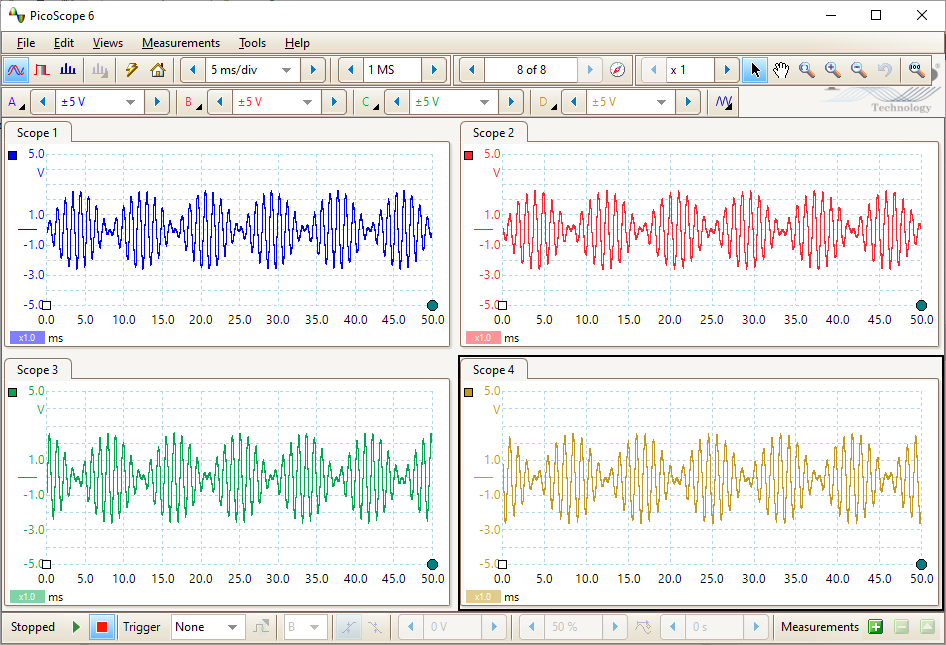

The rotor turns at a constant speed, which is visible when displaying the Resolver Angle signal in SDI. The angle will constantly move between 0 and 2*pi. The Rotor Angle is identical since the Resolver angle offset is set to 0° in the block mask. In the third section, the overshoot flag must remain 0 during the model run.

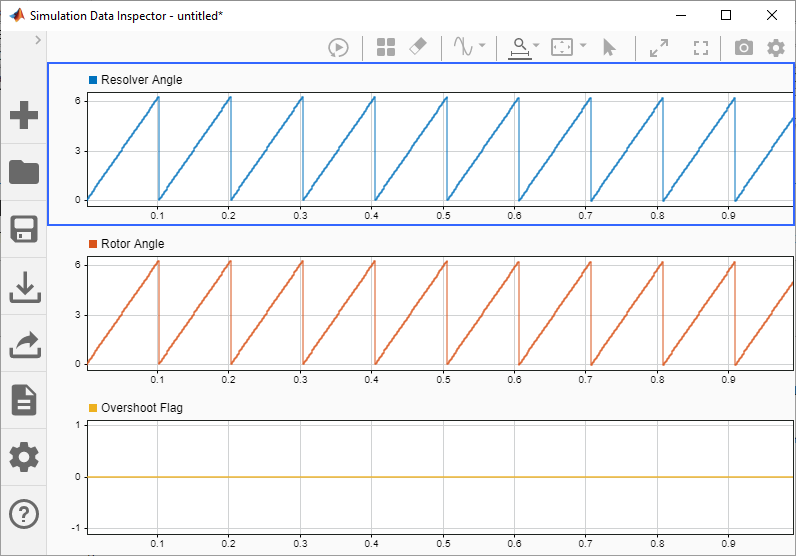

## Additional References

- [Resolver Emulation documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_resolver)